% https://github.com/rlabbe/Kalman-and-Bayesian-Filters-in-Python


lsb_enc = pi/2048;
R_kalman = [lsb_enc/sqrt(12)];


## chpater 7.3.2


cnc_params

G0_accel = 10*tf([mu_ext(1) 0],[tau_ext(1) 1])


G0_accel =
 
     14.48 s
  -------------
  0.04013 s + 1
 
Continuous-time transfer function.
Model Properties


frsp = evalfr(G0_accel,j*24)

frsp = 1.7362e+02 + 1.8029e+02i


max_acc = abs(frsp)

max_acc = 250.3022


max_delta_v = max_acc/500

max_delta_v = 0.5006


a = max_delta_v;

b21 = (k *r /Ra)/J_tilda;
delta_t = 1/500;

rho_sq = (0.72*a)^2

rho_sq = 0.1299

Q732 = diag([0 b21*delta_t*rho_sq ])

Q732 =          0         0
         0    0.0087


## 7.3.1

phi_s = 1;

a22 = -P_ext(2);

Q731 = [
    delta_t^3 ,         (1+a22) * delta_t^2;
  (1+a22) * delta_t^2,   (1+a22)^2 * delta_t
] * phi_s

Q731 =     0.0000   -0.0001
   -0.0001    1.0988


## whitening filter

filelistLAB6PP ="lab6/data/PP/" +  ["Position_control_PP_29-Apr-2025_15-52-56.mat", "Position_control_PP_29-Apr-2025_15-57-33.mat", "Position_control_PP_29-Apr-2025_15-59-58.mat", "Position_control_PP_29-Apr-2025_16-05-57.mat", "Position_control_PP_29-Apr-2025_16-06-47.mat", "Position_control_PP_29-Apr-2025_16-08-04.mat", "Position_control_PP_29-Apr-2025_16-15-38.mat", "Position_control_PP_29-Apr-2025_16-19-46.mat", "Position_control_PP_29-Apr-2025_16-21-40.mat", "Position_control_PP_29-Apr-2025_16-27-10.mat", "Position_control_PP_29-Apr-2025_16-42-20.mat", "Position_control_PP_29-Apr-2025_16-47-32.mat", "Position_control_PP_29-Apr-2025_16-51-46.mat", "Position_control_PP_29-Apr-2025_16-53-53.mat", "Position_control_PP_29-Apr-2025_16-56-11.mat", "Position_control_PP_29-Apr-2025_17-06-15.mat", "Position_control_PP_29-Apr-2025_17-07-34.mat", "Position_control_PP_29-Apr-2025_17-09-36.mat", "Position_control_PP_29-Apr-2025_17-12-23.mat", "Position_control_PP_29-Apr-2025_17-24-13.mat", "Position_control_PP_29-Apr-2025_17-27-12.mat", "Position_control_PP_29-Apr-2025_17-36-36.mat", "Position_control_PP_29-Apr-2025_17-44-09.mat", "Position_control_PP_29-Apr-2025_17-52-13.mat", "Position_control_PP_29-Apr-2025_17-54-56.mat", "Position_control_PP_29-Apr-2025_17-57-36.mat", "Position_control_PP_29-Apr-2025_17-59-27.mat", "Position_control_PP_29-Apr-2025_18-02-38.mat", "Position_control_PP_29-Apr-2025_18-04-42.mat", "Position_control_PP_29-Apr-2025_18-07-34.mat", "Position_control_PP_29-Apr-2025_18-09-31.mat", "Position_control_PP_29-Apr-2025_18-15-12.mat", "Position_control_PP_29-Apr-2025_18-17-45.mat", "Position_control_PP_29-Apr-2025_18-21-45.mat", "Position_control_PP_29-Apr-2025_18-22-36.mat", "Position_control_PP_29-Apr-2025_18-25-08.mat", "Position_control_PP_29-Apr-2025_18-28-11.mat", "Position_control_PP_29-Apr-2025_18-31-08.mat", "Position_control_PP_29-Apr-2025_18-34-28.mat", "Position_control_PP_29-Apr-2025_18-35-20.mat", "Position_control_PP_29-Apr-2025_18-36-40.mat", "Position_control_PP_29-Apr-2025_18-39-17.mat", "Position_control_PP_29-Apr-2025_18-49-00.mat", "Position_control_PP_29-Apr-2025_18-51-45.mat", "Position_control_PP_29-Apr-2025_18-54-05.mat", "Position_control_PP_29-Apr-2025_18-55-32.mat", "Position_control_PP_29-Apr-2025_18-57-08.mat", "Position_control_PP_29-Apr-2025_18-59-52.mat"];
filelistLAB7 ="lab7/data/" + ["Position_control_PP_LQ_09-May-2025_09-41-54.mat","Position_control_PP_LQ_09-May-2025_09-46-37.mat","Position_control_PP_LQ_09-May-2025_09-49-52.mat","Position_control_PP_LQ_09-May-2025_09-54-25.mat","Position_control_PP_LQ_09-May-2025_09-56-21.mat","Position_control_PP_LQ_09-May-2025_09-58-06.mat","Position_control_PP_LQ_09-May-2025_10-04-09.mat","Position_control_PP_LQ_09-May-2025_10-06-05.mat","Position_control_PP_LQ_09-May-2025_10-07-42.mat","Position_control_PP_LQ_09-May-2025_10-11-56.mat","Position_control_PP_LQ_09-May-2025_10-17-29.mat","Position_control_PP_LQ_09-May-2025_10-41-46.mat","Position_control_PP_LQ_09-May-2025_10-45-23.mat","Position_control_PP_LQ_09-May-2025_10-46-43.mat","Position_control_PP_LQ_09-May-2025_10-50-13.mat","Position_control_PP_LQ_09-May-2025_10-57-15.mat","Position_control_PP_LQ_09-May-2025_11-03-03.mat","Position_control_PP_LQ_09-May-2025_11-06-30.mat","Position_control_PP_LQ_09-May-2025_11-15-28.mat","Position_control_PP_LQ_09-May-2025_11-19-17.mat","Position_control_PP_LQ_09-May-2025_11-23-16.mat","Position_control_PP_LQ_09-May-2025_11-28-14.mat","Position_control_PP_LQ_09-May-2025_11-30-18.mat","Position_control_PP_LQ_09-May-2025_11-32-03.mat","Position_control_PP_LQ_09-May-2025_11-35-40.mat","Position_control_PP_LQ_09-May-2025_11-37-48.mat","Position_control_PP_LQ_09-May-2025_11-39-36.mat","Position_control_PP_LQ_09-May-2025_11-40-54.mat","Position_control_PP_LQ_09-May-2025_11-43-09.mat","Position_control_PP_LQ_09-May-2025_11-51-40.mat","Position_control_PP_LQ_09-May-2025_11-52-57.mat","Position_control_PP_LQ_09-May-2025_11-55-47.mat","Position_control_PP_LQ_09-May-2025_12-00-44.mat","Position_control_PP_LQ_09-May-2025_12-01-48.mat","Position_control_PP_LQ_09-May-2025_12-03-19.mat","Position_control_PP_LQ_09-May-2025_12-06-08.mat","Position_control_PP_LQ_09-May-2025_12-08-00.mat","Position_control_PP_LQ_09-May-2025_12-25-50.mat","Position_control_PP_LQ_09-May-2025_12-28-08.mat","Position_control_PP_LQ_09-May-2025_12-32-00.mat","Position_control_PP_LQ_09-May-2025_12-36-10.mat","Position_control_PP_LQ_09-May-2025_12-38-26.mat","Position_control_PP_LQ_09-May-2025_12-51-28.mat","Position_control_PP_LQ_09-May-2025_12-54-32.mat"];



Motor0Files = [filelistLAB6PP(18); filelistLAB6PP(19); filelistLAB6PP(21) ;
filelistLAB7(11)  ;  filelistLAB7(12) ; filelistLAB7(13);  filelistLAB7(14)   
];

Motor1Files = [ filelistLAB6PP(22); filelistLAB6PP(23) ;
filelistLAB7(15)];

% mot 0

G0_ss_discrete = c2d(G0_ss,1/500);
Ad = G0_ss_discrete.A;
Bd = G0_ss_discrete.B;

m0_opt_rho = [];
for exper = 1:size(Motor0Files,1)
data = load(Motor0Files(exper)).data;
t = data(1,:);
y = data(2,:);
u = data(6,:);
sys = G0_ss;
m0_opt_rho(exper) = plotResidualLanscape(t,y,u,sys,false);
end
m0_opt_rho

m0_opt_rho =     0.1700    0.2100    0.2100    0.1900    0.1900    0.2000    0.1900





m1_opt_rho = [];
for exper = 1:size(Motor1Files,1)
data = load(Motor1Files(exper)).data;
t = data(1,:);
y = data(3,:);
u = data(7,:);
sys = G1_ss;
m1_opt_rho(exper) = plotResidualLanscape(t,y,u,sys,false);
end
m1_opt_rho

m1_opt_rho =     0.1400    0.1400    0.1500


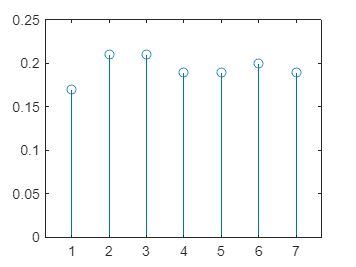

figure
stem(m0_opt_rho)

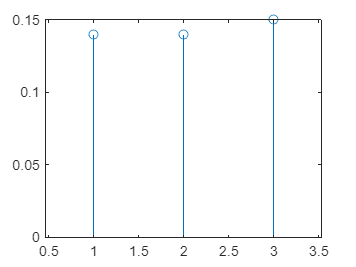

% ylim([0 0.25])

figure
stem(m1_opt_rho)

% ylim([0 0.25])



% 
% lag_size =20;
% lags = -lag_size:1:lag_size;
% test = 1:100;
% rho = 1e-2.*test;
% 
% [RHO,LAGS] = meshgrid(rho,lags);
% AC = zeros(1+lag_size*2,size(rho,2));
% norm_tau =rho.*0;
% 
% 
% for i = 1:size(rho,2)
% 
% Q_kalman = rho(i) * diag([0 1]);
% 
% [L_kf,S_kf,P_kf] = lqrd(G0_ss.A',G0_ss.C',Q_kalman,R_kalman,1/500);
% L_kf = L_kf';
% 
% x_hat = zeros(2,kf_steps);
% 
% kf_steps = size(t,2);
% e = zeros(1,kf_steps);
% y_hat = e;
% 
% for k = 2:kf_steps-1
%     y_hat(k) = x_hat(1,k);
%     e(k) = y(k)- y_hat(k) ;
%     x_hat(:,k+1) = Ad*x_hat(:,k) + Bd*u(k) + L_kf * e(k);
% 
% 
% end
% 
% 
% % figure
% % plot(t,e)
% % hold on
% % plot(t,y_hat)
% % plot(t,y)
% % hold off
% % 
% % legend(["e","y_hat","y"])
% 
% 
% 
% 
% 
% [autocorr,lagscorr] = xcorr(e,e,20,'normalized');
% autocorr(lag_size+1)=0;
% autocorr= (autocorr').^3;
% AC(:,i) = autocorr;
% 
% norm_tau(i) = norm(autocorr);
% % figure
% % stem(lagscorr,autocorr)
% 
% 
% end
% 
% 
% [min_tau, min_idx] = min(norm_tau);
% figure
% subplot(2,4,[1 2 3 4])
% sgtitle("Residuals landscape")
% mesh(RHO,LAGS,AC)
% xlabel("rho")
% ylabel("lag (k)")
% zlabel("auto corr")
% 
% 
% subplot(2,4,6)
% stem(LAGS(:,1),AC(:,1))
% ylim([-1 1])
% xlabel("lag (k)")
% ylabel("auto corr")
% title("rho = "+rho(1))
% 
% subplot(2,4,7)
% stem(LAGS(:,min_idx),AC(:,min_idx))
% ylim([-1 1])
% xlabel("lag (k)")
% ylabel("auto corr")
% title("rho = "+rho(min_idx))
% 
% subplot(2,4,8)
% stem(LAGS(:,end),AC(:,end))
% ylim([-1 1])
% xlabel("lag (k)")
% ylabel("auto corr")
% title("rho = "+rho(end))
% 
% 
% subplot(2,4,5)
% rho_min = rho(min_idx);
% plot(rho,norm_tau)
% line([rho_min rho_min],[0 max(norm_tau)])
% title("L2 norm of error residuals")
% 
% end
% 


function [optRho] = plotResidualLanscape(t,y,u,sys,doPlot)

sys_discrete = c2d(sys,1/500);
Ad = sys_discrete.A;
Bd = sys_discrete.B;


lsb_enc = pi/2048;
R_kalman = [lsb_enc/sqrt(12)];

lag_size =20;
lags = -lag_size:1:lag_size;
test = 1:100;
rho = 1e-2.*test;

[RHO,LAGS] = meshgrid(rho,lags);
AC = zeros(1+lag_size*2,size(rho,2));
norm_tau =rho.*0;


for i = 1:size(rho,2)

Q_kalman = rho(i) * diag([0 1]);

[L_kf,~,~] = lqrd(sys.A',sys.C',Q_kalman,R_kalman,1/500);
L_kf = L_kf';

kf_steps = size(t,2);
x_hat = zeros(2,kf_steps);

e = zeros(1,kf_steps);
y_hat = e;

for k = 2:kf_steps-1
    y_hat(k) = x_hat(1,k);
    e(k) = y(k)- y_hat(k) ;
    x_hat(:,k+1) = Ad*x_hat(:,k) + Bd*u(k) + L_kf * e(k);
    
    
end


% figure
% plot(t,e)
% hold on
% plot(t,y_hat)
% plot(t,y)
% hold off
% 
% legend(["e","y_hat","y"])





[autocorr,~] = xcorr(e,e,20,'normalized');
autocorr(lag_size+1)=0;
autocorr= (autocorr').^3;
AC(:,i) = autocorr;

norm_tau(i) = norm(autocorr);
% figure
% stem(lagscorr,autocorr)


end

[~, min_idx] = min(norm_tau);
rho_min = rho(min_idx);


if doPlot
figure
subplot(2,4,[1 2 3 4])
sgtitle("Residuals landscape")
mesh(RHO,LAGS,AC)
xlabel("rho")
ylabel("lag (k)")
zlabel("auto corr")


subplot(2,4,6)
stem(LAGS(:,1),AC(:,1))
ylim([-1 1])
xlabel("lag (k)")
ylabel("auto corr")
title("rho = "+rho(1))

subplot(2,4,7)
stem(LAGS(:,min_idx),AC(:,min_idx))
ylim([-1 1])
xlabel("lag (k)")
ylabel("auto corr")
title("rho = "+rho(min_idx))

subplot(2,4,8)
stem(LAGS(:,end),AC(:,end))
ylim([-1 1])
xlabel("lag (k)")
ylabel("auto corr")
title("rho = "+rho(end))


subplot(2,4,5)
plot(rho,norm_tau)
line([rho_min rho_min],[0 max(norm_tau)])
title("L2 norm of error residuals")
end
optRho = rho_min;
end